data = load('resultadosCSV_magic.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

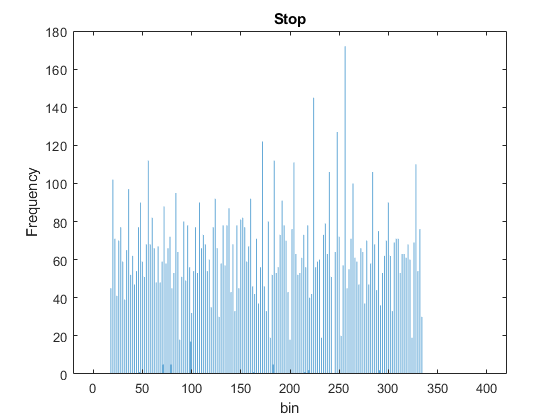

clf;
fig = figure;
bordes      = -0.5:1:400.5;
h1           = histogram(stop, bordes); title('Stop'); xlabel('bin'); ylabel('Frequency');
h1.EdgeColor = 'none';
bines_stop  = h1.BinCounts;
% saveas(gcf,'histograma_stop.eps', 'eps');
exportgraphics(fig,'histograma_stop.eps')


maxbin_stop = max(find(bines_stop, 1, 'last'))-1

maxbin_stop = 334

minbin_stop = min(find(bines_stop, 1, 'first'))-1

minbin_stop = 18

Nc_stop     = maxbin_stop - minbin_stop

Nc_stop = 316



T   = 5e-9;
tau = T/Nc_stop

tau = 1.5823e-11

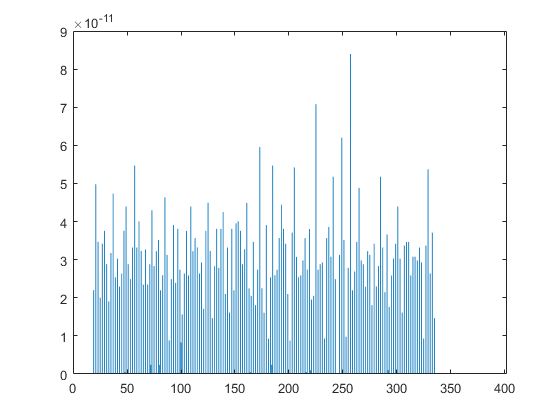

tau_stop = tau;

%%Real

N           = length(stop);    %numero de ensayos

ti_stop         = bines_stop*(T/N);
bar(ti_stop)

t = tiledlayout(3,1);

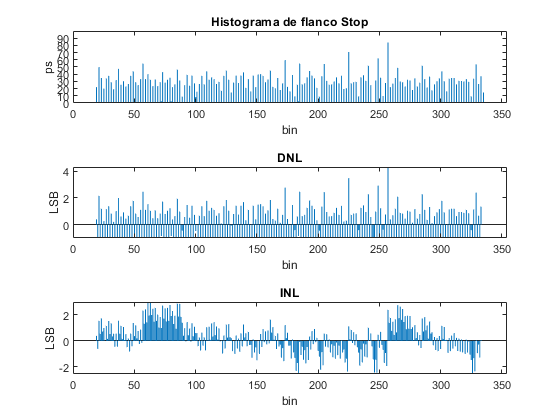

%Histograma
nexttile;

bar(ti_stop(1, 1:353)); ylabel('ps'); xlabel('bin'); title('Histograma de flanco Stop');
ax = gca; 
valoresY = ax.YAxis.TickValues;
% ax.YAxis.TickValuesMode = "manual";
yticks([0 10 20 30 40 50 60 70 80 90]*1e-12)
yticklabels({0 10 20 30 40 50 60 70 80 90})

%DNL
nexttile;
dnl_stop = (ti_stop - tau)/tau;
dnl_stop(1, 1:minbin_stop) = 0;
dnl_stop(1, maxbin_stop:end) = 0;
bar(dnl_stop(1, 1:353)); ylabel('LSB'); xlabel('bin'); title('DNL')

%INL
nexttile;
inl_stop = cumsum(dnl_stop);
inl_stop(1, maxbin_stop:end) = 0;
bar(inl_stop(1:353)); ylabel('LSB'); xlabel('bin'); title('INL')

exportgraphics(t,'linealidad_stop.eps')

% saveas(gcf,'linealidad_stop.eps', 'eps');

% clf;
% % x_tiempo = 0:tau_stop:(tau_stop*Nc_stop);
% format short
% x_tiempo = 0:319-1;
% y_ideal  = 0:length(x_tiempo)-1;
% y_real = inl_i(1, minbin_stop:maxbin_stop) + y_ideal;
% % plot(x_tiempo, y_ideal, x_tiempo, y_real);
% stairs(x_tiempo, y_ideal, 'r--');
% hold on;
% stairs(x_tiempo, y_real, 'b')
% hold off;
% xlabel('n\tau'); ylabel('Codigo de salida');
% legend('Ideal', 'Transferencia del flanco Stop');
% ax = gca; 
% ax.XLim = [0, max(x_tiempo)];
% % saveas(gcf,'transferencia_stop.eps', 'eps');
% exportgraphics(gcf,'transferencia_stop.eps')

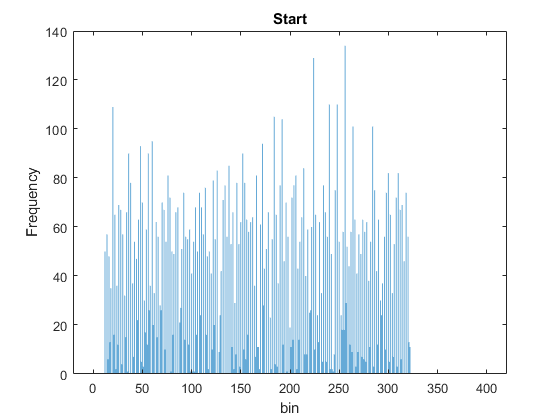

clf;
fig = figure();
bordes      = -0.5:1:400.5;
h           = histogram(start, bordes); title('Start'); xlabel('bin'); ylabel('Frequency');
h.EdgeColor = 'none';
bines_start = h.BinCounts;
exportgraphics(fig,'histograma_start.eps');

% export_fig('prueba','-eps', '-r600');
    
maxbin_start = max(find(bines_start, 1, 'last'))

maxbin_start = 323

minbin_start = min(find(bines_start, 1, 'first'))

minbin_start = 13

Nc_start     = maxbin_start - minbin_start

Nc_start = 310


%%Ideal
T   = 5e-9;
tau_start = T/Nc_start

tau_start = 1.6129e-11


%%Real
clf;
N           = length(start);    %numero de ensayos

t_start = tiledlayout(3,1)

t_start =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


%Histograma
nexttile;
ti_start         = bines_start*(T/N);
bar(ti_start(1, 1:353)); ylabel('ps'); xlabel('bin'); title('Histograma de flanco Start')
ax = gca; 
valoresY = ax.YAxis.TickValues;
% ax.YAxis.TickValuesMode = "manual";
yticks([0 10 20 30 40 50 60 70]*1e-12)
yticklabels({0 10 20 30 40 50 60 70})

%DNL
nexttile;
dnl_start = (ti_start - tau_start)/tau_start;
dnl_start(1, 1:minbin_start) = 0;
dnl_start(1, maxbin_start:end) = 0;
bar(dnl_start(1, 1:353)); ylabel('LSB'); xlabel('bin'); title('DNL')

%INL
nexttile;
inl_start = cumsum(dnl_start)

inl_start =          0         0         0         0         0         0         0         0         0         0         0         0         0   -1.0000   -0.2744   -1.0928   -0.6396   -1.2461   -1.1865   -2.1865    0.1133   -0.4023    0.5654   -0.3740   -0.2842   -0.9209    0.1680   -0.8320    0.1963   -0.6826    0.0430   -0.9570   -0.9883   -1.5342   -0.5361   -1.5059    0.2188   -0.7812    0.5801   -0.4199   -0.2998   -1.0879   -0.4531   -1.4531   -1.0303   -1.3643   -0.4570   -1.4570    0.3584   -0.4902


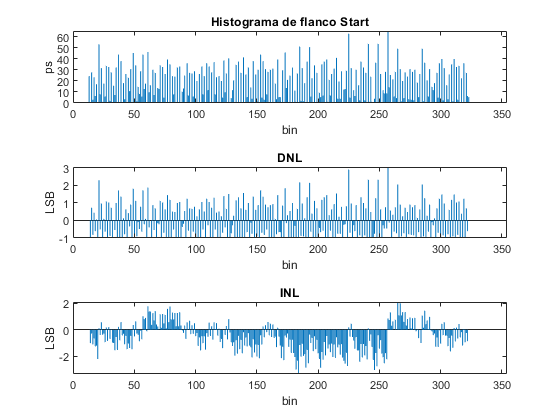

inl_start(1, maxbin_start:end) = 0;
bar(inl_start(1:353)); ylabel('LSB'); xlabel('bin'); title('INL')

exportgraphics(t_start,'linealidad_start.eps');

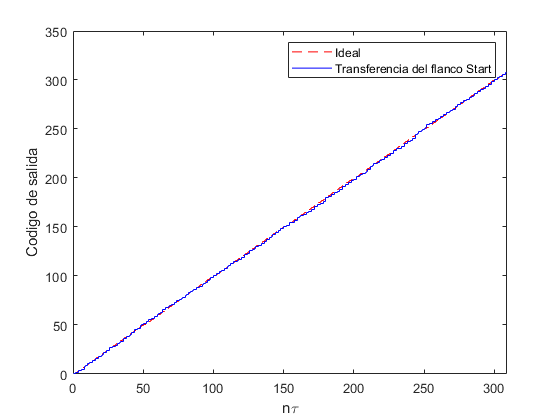


clf;
% x_tiempo = 0:tau_stop:(tau_stop*Nc_stop);
format short
x_tiempo = 0:Nc_start-1;
y_ideal  = 0:length(x_tiempo)-1;
y_real = inl_start(1, minbin_start:maxbin_start-1)+y_ideal;
% plot(x_tiempo, y_ideal, x_tiempo, y_real);
stairs(x_tiempo, y_ideal, 'r--');
hold on;
stairs(x_tiempo, y_real, 'b')
hold off;
xlabel('n\tau'); ylabel('Codigo de salida');
legend('Ideal', 'Transferencia del flanco Start');
ax = gca; 
ax.XLim = [0, max(x_tiempo)];
exportgraphics(gcf,'transferencia_start.eps');

# Calibración

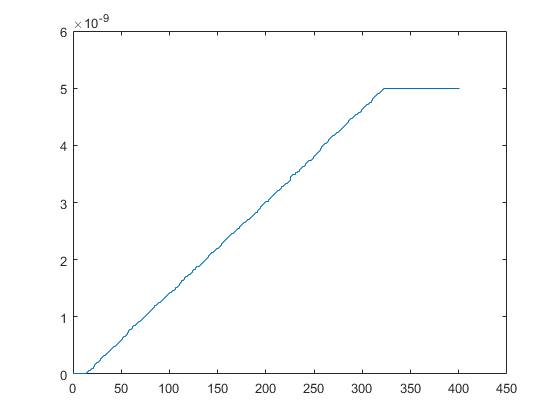

clf;

cumsum_start = cumsum([0, ti_start]);
cal_start =   cumsum_start(1:end-1) + ti_start/2;
stairs(cal_start);

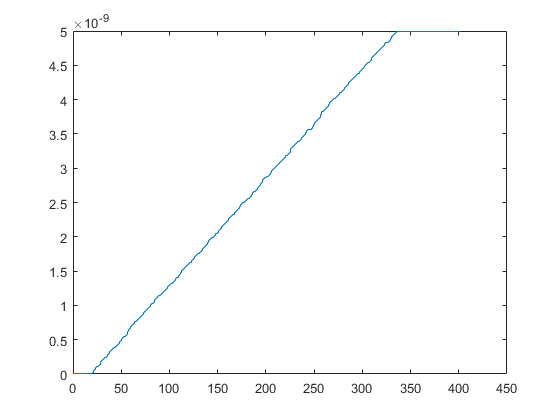


cumsum_stop = cumsum([0, ti_stop]);
cal_stop =   cumsum_stop(1:end-1) + ti_stop/2;
stairs(cal_stop);


%GUARDAR CALIBRACION!
save('DatosCalibracion.mat', 'tau', 'maxbin_start', 'minbin_start', 'maxbin_stop', 'minbin_stop', 'tau_start', 'tau_stop', 'cal_stop', 'cal_start');